# Spectral Factor Model Order Reduction

## Introduction

Spectral Factor MOR presented in [1] is a model order reduction method suited for passive systems. The algorithm is based on the spectral factorization of the Popov function obtained by solving the Kalman-Yakubovic-Popov (KYP) inequality. Model reduction is applied to the spectral factor. Thereby, unstructured methods, e.g. IRKA [2] can be utilized. Passivity is preserved by inverting the construction of the spectral factor by means of a Lyapunov equation.  

### The idea

First, a solution $X=X^\mathrm{T} \ge 0$ to the KYP inequality $\mathcal{W}(X)$ for the FOM needs to be found. Afterwards, a Cholesky-like factorization $\mathcal{W}(X) = [\matrix{L & M}]^\mathrm{T} [\matrix{L & M}]$ is computed to construct the spectral factor $\Sigma_H = (A,B,L,M)$. The spectral factor is reduced with an unstructured reduction algorithm, e.g. IRKA, obtaining $\hat{\Sigma}_H = (\hat{A}, \hat{B}, \hat{L}, \hat{M})$, which is of order *r*. Next, one constructs the reduced feed-through and output matrix. To this end, one sets $\hat{D} = \frac{1}{2} \hat{M}^\mathrm{T}\hat{M} + \text{skew}(D)$ and solves $\hat{A}^\mathrm{T} \hat{X} + \hat{X} \hat{A} + \hat{L}^\mathrm{T} \hat{L} = 0$, where $\hat{X} \in \mathbb{R}^{r \times r}, \hat{X} = \hat{X}^\mathrm{T} \ge 0$. Set $\hat{C} = \hat{B}^\mathrm{T} \hat{X} + \hat{M}^\mathrm{T} \hat{L}$. With this one can construct the passive ROM as $\hat{\Sigma} = (\hat{A},\hat{B},\hat{C},\hat{D})$.

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of Spectral Factor MOR in the function *sfmor*.

For more information, refer to the documentation:

help sfmor

  sfmor - Obtain a passive reduced order model by applying an sss-MOR method
          to the spectral factor of system sys and computing a reduced
          model for the associated reduced spectral factor
 
  Syntax:
    sysr = sfmor(fctHandle, sys)
    sysr = sfmor(fctHandle, sys, Opts)
 
  Description:
        sysr = sfmor(fctHandle, sys) computes a reduced order model by
        applying model reduction to the spectral
        factor [1] of sys and subsequently reversing the construction of
        the spectral factor.
 
  Input Arguments:
        *Required Input Arguments:*
        - fctHandle:    function handle to the MOR function that is applied to
                        the spectral factor
        - sys:          sss (phs) object, containing passive LTI (port-Hamiltonian) system
 
        *Optional Input Arguments:*
        - additional inputs to @fctHandle except options
        - Opts:  structure with execution parameters


## Example

The example considered here is a SISO Ladder Network with an architecture as shown below:  

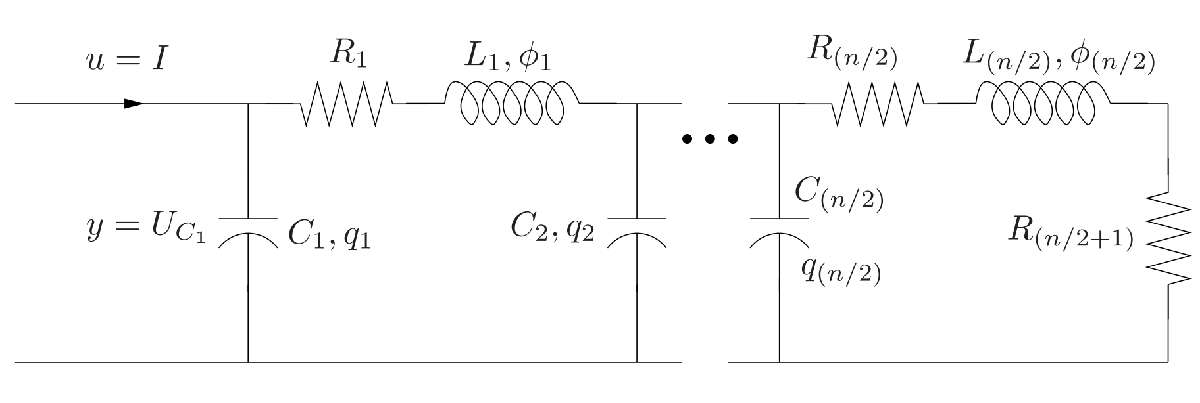

Image source: [3]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.2\text{H}$), 50 capacitors ($C_i = 0.2\text{F}$) and 51 resistances ($R_i=1\Omega$).

sys = sss(setup_LadderNetworkSystem(100,.2,.2,1))

sys =   (SSS)(SISO)
  100 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


*sfmor* in its simplest form is called by providing a function handle to the desired reduction method, the system to reduce and the desired reduced order (depending on the reduction scheme):

sysr = sfmor(@irka, sys, 10)

IRKA step 007 - Convergence (s0):  3.1e-04 

sysr =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10
   x1      -3.331      18.33      10.67      3.865      2.887      0.709   -0.02882   0.002571   -0.01545    -0.1044
   x2      -4.325     -3.331      -3.16     0.7373     -1.097     0.2428    -0.5655   0.002895   -0.06703    -0.2152
   x3           0          0      -5.02     -9.155     -6.627     0.1334    0.06443   -0.01105     0.1444     0.5143
   x4           0          0      3.929      -5.02     -5.692     -1.497     -1.211   0.007585    -0.1897    -0.4963
   x5           0          0          0          0     -4.231     -2.455     -1.558    0.01548    -0.3263    -0.9265
   x6           0          0          0          0          0     -1.153    -0.5491   0.002748    -0.0577     -0.194
   x7           0          0          0          0          0          0    -0.4035  -0.002879    0.04718     0.1275
   

norm(sys - sysr)

ans = 5.4290e-04

isPassive(ss(sysr))

ans = logical
   1


### Options

Since *sfmor* is such a high-level algorithm, it provides many (nested) options. The levels of options are:

- Top level (*sfmor*): e.g. ARE solver

- Second level (*ss2phs, irka (if used as reduction method)*): e.g. port-Hamiltonian representation, maximum iterations of IRKA

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help ss2phs

  ss2phs - Returns pH system representation of a given passive system
 
  Syntax:
    sysPH = ss2phs(sys)
    sysPH = ss2phs(sys,X)
    sysPH = ss2phs(sys,Opts)
    sysPH = ss2phs(sys,X,Opts)
 
  Description:
        This funciton uses the Kalman-Yakubovic-Popov Lemma to construct a
        port-Hamiltonian system representation of a given passive
        ss object.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  ss object to be brought in pH representation
        *Optional Input Arguments:*
        - X: solution to positive real Riccati equation
        - Opts: structure with execution parameters
            - .tol:             If D+D' is not positive definite, D is replaced
                                by Opts.tol*eye(m).
                                [{1e-12} / positive double]
            - .representation:  Defines the pH system representation
                       

To provide these options, use nested structs. As example, the following code changes the ARE solver and specifies that a pH system is constructed. Furthermore, the IRKA convergence conditions are changed:

Opts = struct();
Opts.makePH = true;     % Transform to pH representation
Opts.are = 'icare';     % Function to solve are

% IRKA options
Opts.irka.maxiter = 200;
Opts.irka.stopCrit = 's0';
Opts.irka.tol = 1e-5;

Opts

Opts = struct with fields:
    makePH: 1
       are: 'icare'
      irka: [1×1 struct]



sysr = sfmor(@irka,sys,10,Opts)

IRKA step 009 - Convergence (s0):  7.6e-06 


sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @sfmor
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


norm(ss(sys) - ss(sysr))

ans = 5.4337e-04

isPassive(ss(sysr))

ans = logical
   1


### Output

*sfmor* provides only the reduced system as output. This ssRed object contains additional information which makes the creation more transparent:

sysr.method       % Method with which the system was created (should be @sfmor)

ans = function_handle with value:
    @sfmor


sysr.parameters     % Execution parameters (options)

ans = struct with fields:
            makePH: 1
               are: 'icare'
              irka: [1×1 struct]
         backtrafo: 'popov'
               tol: 1.0000e-12
              lyap: 'lyap'
    checkPassivity: 0
               phs: [1×1 struct]
            ss2phs: [1×1 struct]
        samPassive: [1×1 struct]
           areOpts: [1×1 struct]
          lyapOpts: [1×1 struct]
             sysSS: [1×1 ssRed]


## References

[1] T. Breiten and B. Unger. “Passivity preserving model reduction via spectral factorization." In: Automatica 142 (2022), p. 110368.

[2] S. Gugercin, A. C. Antoulas, and C. A. Beattie. *H*2 Model Reduction for Large-Scale Linear Dynamical Systems. *SIAM J. Matrix Anal. Appl.*, 30(2):609–638, 2008.

[3] R. V. Polyuga, "Model reduction of port-Hamiltonian systems", PhD thesis, University of Groningen, 2010.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)